%% Manipulate the mass-spring damper equation using symbolic operations
% The mass-spring-damper differntial equation that you derived in the previous 
% section is 
% 
% m

syms x x_dot x_ddot m c k F
%%
msdEq = m*x_ddot + c*x_dot + k*x  == F % Replace NaN with your equation

$$msdEq = c\,\dot{x}+k\,x+m\,\ddot{x}=F$$

%%
sltnMSD = solve(msdEq,x_ddot)

$$sltnMSD = -\frac{c\,\dot{x}-F+k\,x}{m}$$

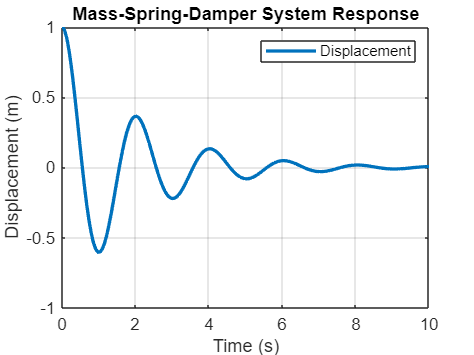

%%
 % Mass-Spring-Damper System Simulation
 % Define system parameters
m = 1;   % Mass (kg)
 k = 10;  % Spring constant (N/m)
 c = 1;   % Damping coefficient (N·s/m)
%%
% Define time span for simulation
 tspan = [0 10];
%%
% Define initial conditions [initial position, initial velocity]
 y0 = [1; 0];
%%
 % Define the system of differential equations
 % y(1) = position, y(2) = velocity
 dydt = @(t, y) [y(2); -c/m * y(2) - k/m * y(1)];
%%
 % Solve the differential equation using ode45
 [t, y] = ode45(dydt, tspan, y0);
%%
% Plot the results
 figure;
 plot(t, y(:,1), 'LineWidth', 2);
 title('Mass-Spring-Damper System Response');
 xlabel('Time (s)');
 ylabel('Displacement (m)');
 grid on;
 legend('Displacement')

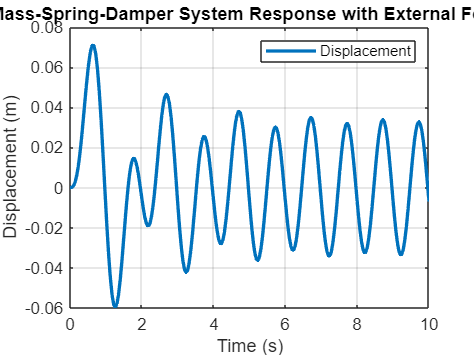

%%
 % Define the external force as a function of time
 F = @(t) sin(2 * pi * t);  % Example: sinusoidal force with frequency of 1 Hz
%%
 % Define time span for simulation
 tspan = [0 10];
 % Define initial conditions [initial position, initial velocity]
 y0 = [0; 0];
%%
 % Define the system of differential equations
 % y(1) = position, y(2) = velocity
 dydt = @(t, y) [y(2); (F(t) - c * y(2) - k * y(1)) / m];
 % Solve the differential equation using ode45
 [t, y] = ode45(dydt, tspan, y0);
%%
% Plot the results
 figure;
 plot(t, y(:,1), 'LineWidth', 2);
 title('Mass-Spring-Damper System Response with External Force');
 xlabel('Time (s)');
 ylabel('Displacement (m)');
 grid on;
 legend('Displacement');

% Define the system of first-order ODEs
function dydt = ode_system(t , x)
    dydt = zeros(2,1);
    dydt(1) = x(2);  % dy1/dt = y2
    dydt(2) = 20 - 7*x(2) - 10*x(1);  % dy2/dt = 20 - 7*y2 - 10*y1
end

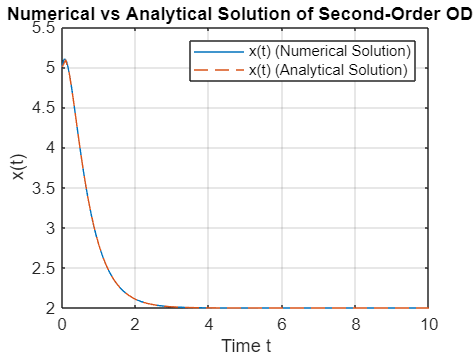

% Initial conditions
x0 = [5; 3];  % y1(0) = 5, y2(0) = 3
% Time span
tspan = [0 10];  % Solve from t = 0 to t = 10
% Solve the ODE using ode45
[t, x] = ode45(@ode_system, tspan, x0);
% Plot the results
figure;
plot(t, x(:,1),  'DisplayName', 'x(t) (Numerical Solution)');
hold on;
% Analytical solution
y_analytical = @(t) 6*exp(-2*t) - 3*exp(-5*t) + 2;
t_analytical = linspace(0, 10, 100);
y_analytical_values = y_analytical(t_analytical);
plot(t_analytical, y_analytical_values, '--', 'DisplayName', 'x(t) (Analytical Solution)');
xlabel('Time t');
ylabel('x(t)');
title('Numerical vs Analytical Solution of Second-Order ODE');
legend;
grid on;
hold off;